## **SynDiag: Synthetic Diagnostics Simulation Module in TokaLab**

TokaLab includes a dedicated module, **SynDiag**, for simulating diagnostics and their measurements. This Live Script introduces and explains SynDiag in detail.

A **synthetic diagnostic** simulates a diagnostic system at varying levels of complexity. For example, consider simulating an air temperature measurement using a mercury thermometer. The temperature field is known at every point in the simulated environment (e.g., a room). The diagnostic can be modeled with different degrees of fidelity: you might sample the temperature near the thermometer’s location, or simulate the fluid expansion in the thermometer bulb based on heat exchange, deriving the temperature difference from the reference state. This flexibility allows users to balance computational demands with the desired level of detail.

Currently, SynDiag supports six diagnostic types:

- Pick-up coils

- Flux loops

- Saddle loops

- Thomson Scattering

- Interferometer-polarimeter

- Bolometric diagnostics

Each of these will be briefly explained in the following section.

### 1. How Diagnostics' Simulations are organised

The simulation process for each diagnostic follows a standardized structure, consisting of three primary functions:

- **Initialization**: A routine that prepares the diagnostic for the subsequent steps.

- **Upload**: This function loads a specific configuration for the diagnostic (e.g., position, laser settings for laser-based diagnostics). SynDiag includes predefined configurations for JET, DTT, and TokaLab, but users can add custom configurations by modifying the "configuration" condition in the `Upload` function of each diagnostic’s class.

- **Measurement**: Using reference fields from the equilibrium, this function simulates measurements—either by interpolating the reference field at the diagnostic’s location or by processing the fields to produce line-integrated data. Noise can also be added to the simulated measurements to better replicate real-world conditions. The specifics of this process are unique to each diagnostic and will be explored further in their respective sections.

**Script Organization**

The Live Script is structured as follows:

- The first section recaps the equilibrium simulation performed by **SimPla**.

- The next section introduces all the diagnostics, explaining their operating principles and the synthetic measurement process.

- Each diagnostic subsection concludes with examples demonstrating how parameter modifications affect the simulated results.

**Preparing for Simulation**

To simulate diagnostics and their measurements, begin by clearing the workspace, loading a machine, and solving the equilibrium. For more details, refer to **SimPla Live Script**.

Like SimPla, SynDiag adheres to principles of modularity and integrability: once a machine is selected and diagnostic configurations are set, SynDiag operates as a fully modular system.

VirtualLab_init()

new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/apps
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/docs
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/DataGen_MATLAB
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/DataGen_MATLAB/functions_dg
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/DataGen_MATLAB/config_dg
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/examples
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/SimPla_MATLAB
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/SimPla_MATLAB/functions
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/SimPla_MATLAB/tokamaks
new added path : C:\Users\novel\OneDrive\TokaLab\VirtualLab\VirtualLab_MatLab/SimPla_MATLAB/tokamaks/equilibrium
new added path : C:\Users\novel\OneDr


clear; clc;
clf
close all

machine = "TokaLab";

% initialise the class tokamak
tok = tokamak();

% upload the geometry information of your tokamak
tok = tok.machine_upload(machine);

TokaLab


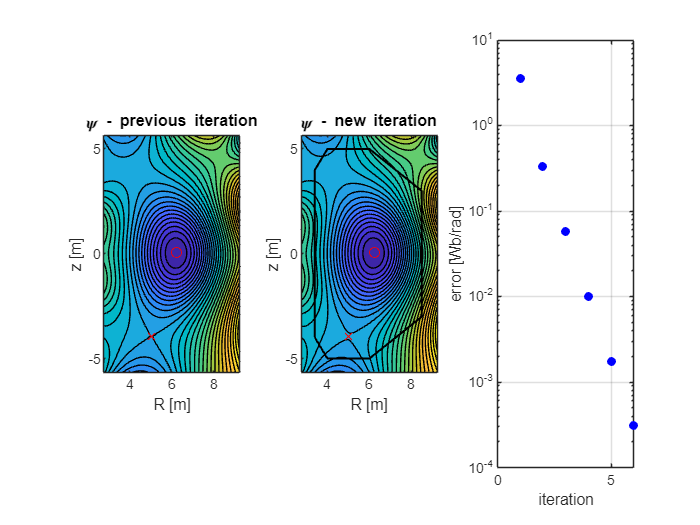

tok = tok.scenario_upload(1);
tok = tok.kinetic_upload();

% initialise the class geometry
geo = geometry;
geo = geo.import_geometry(tok);
geo = geo.build_geometry();
geo = geo.inside_wall();

% initialise the equlibrium class
equi = equilibrium;
equi = equi.import_configuration(geo,tok.config);
equi = equi.import_classes();
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);

new_points_R = [];
new_points_Z = [];

equi = equi.solve_equilibrium_dimless();

equi = equi.equi_pp2();

equi  = equi.compute_profiles();

### 2. SynDiag: from diagnostics to synthetic ones

In this Section a brief explanation of each diagnostic and a presentation of the respective simulation code are provided. 

### 2.1 Pick-Up Coils

Pick-Up Coils are magnetic induction sensors measuring the local magnetic field induced along the coil axis unitary vecor (n) representing the coil's direction respect to the machine's frame of reference ([Donné at al, 2007](https://doi.org/10.1088/0029-5515/47/6/S07), [Hutchinson, 2002](https://doi.org/10.1017/CBO978051161363), [Wesson, 2014](https://scipub.euro-fusion.org/wp-content/uploads/2014/11/JETR99013.pdf)). Beeing i the i-th measurement, each measurement is modelled as reproted below (bein R_i and Z_i the coordinate of each coil's centre): 


$$B_{{\textrm{PU}}_i } =\mathit{\mathbf{B}}\left(R_i ,Z_i \right)\cdot n\left(R_i ,Z_i \right)$$


All the quantities of interest to simulate this diagnostic are defined in the properties section of the class Diag_PickUpCoils and are:

- R, the horizontal coordinate

- Z, the vertical coordinate

- n, the coil's normal unitary vector

- B, the measured magnetic field

- $\sigma_B$, the associated uncertainty to measure the magnetic field

- unit, the unit of measurement, in this case [T]

- config, the structure containing the information related to the configuration

- ideal, the structure containing the measurements without noise

To introduce the class, we firstly need to initialise it in the workspace:

PickUp = Diag_PickUpCoils(); % To initialise the diagnostic
PickUp = PickUp.Upload(1,machine); % To upload the configuration and the geometrical data 
PickUp = PickUp.measure(equi); % To simulate the measurements

The function **measure **consists of the interpolation of magnetic field components $B_R ,B_{\phi } ,B_z$ in the points $\left(R_i ,Z_i \right)$, coordinates of each coil's centre. Then, the scalar product with the unitary vector n (defined as a parameter in the Upload function) is evaluated.

To make the simulated measurement resemble the real one, noise is added. More specifically, it is possible to perturbate the ideal measurements obtained with both an absolute noise and a proportional one (in this configuration set equal to zero, see Example 1 for a different setting of noise):

disp(PickUp.config.noise_random_absolute_intensity)

     0



disp(PickUp.config.noise_random_proportional_intensity)

     0



 The resulting measurement will be the ideal one (coming from the interpolation) and the added noise (which is an input parameter that can be selected in the Upload function). It is also possible to determine the measurement's associated uncertainty defined as: 


$$\sigma_B =\sqrt{\;\textrm{Noise}\;\textrm{Random}\;\textrm{Absolute}\;{\textrm{Intensity}}^2 +{\left({\textrm{Ideal}}_B \cdot \textrm{Noise}\;\textrm{Random}\;\textrm{Proportional}\;\textrm{Intensity}\right)}^2 }$$


  disp(PickUp.sigma_B)

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



For what concerns the function Upload, it is organised as follows: at first some if conditions on user's input are introduced to avoid error on missing entries.

Then, different cnfigurations are defined. By adding another condition on the if condition, the user is able to introduce new configurations. At the moment three of them are defined: the TokaLab standard (configuration == 1), the JET-like (configuration == 2) and the DTT-like (configuration == 3). To add a new one, the user can create a .mat file, as the one present in the subfolders in the diagnostics' folder or can define the necessary quantities (n, R, Z) directly inside the Upload function. 

The last function contained in this class is a simple plot function to show the location of the pick-up coils and to plot measurements produced by the simulated diagnostic. 

Now, let us make some example.

#### 2.1.1 Example 1: Different geometries 

PickUp = Diag_PickUpCoils(); % To initialise the diagnostic
PickUp = PickUp.Upload(1,machine); % To upload the configuration and the geometrical data 
PickUp = PickUp.measure(equi); % To simulate the measurements


%% To introduce a new geometry it is necessary to run again the equilibrium
tok_JET = tokamak();

% upload the geometry information of your tokamak
machine_JET = "JET-like";
tok_JET = tok_JET.machine_upload(machine_JET);

JET-like


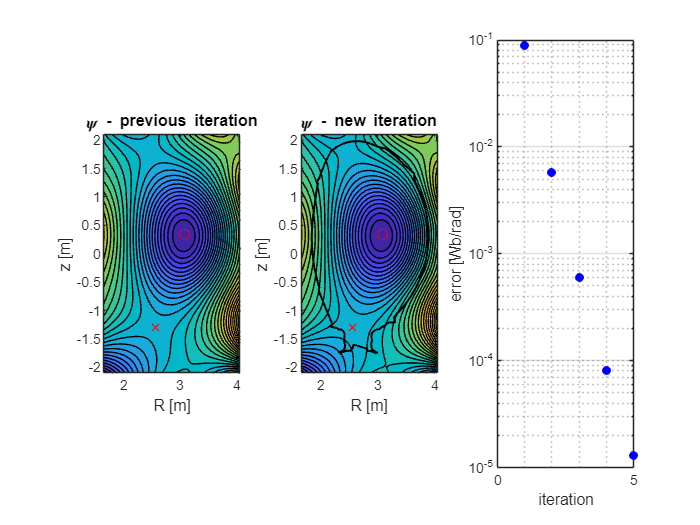

tok_JET = tok_JET.scenario_upload(1);
tok_JET = tok_JET.kinetic_upload();

% initialise the class geometry
geo_JET = geometry;
geo_JET = geo_JET.import_geometry(tok_JET);
geo_JET = geo_JET.build_geometry();
geo_JET = geo_JET.inside_wall();

% initialise the equlibrium class
equi_JET = equilibrium;
equi_JET = equi_JET.import_configuration(geo_JET,tok_JET.config);
equi_JET = equi_JET.import_classes();
equi_JET.separatrix = equi_JET.separatrix.build_separatrix(equi_JET.config.separatrix,equi_JET.geo);

new_points_R = [];
new_points_Z = [];

equi_JET = equi_JET.solve_equilibrium_dimless();

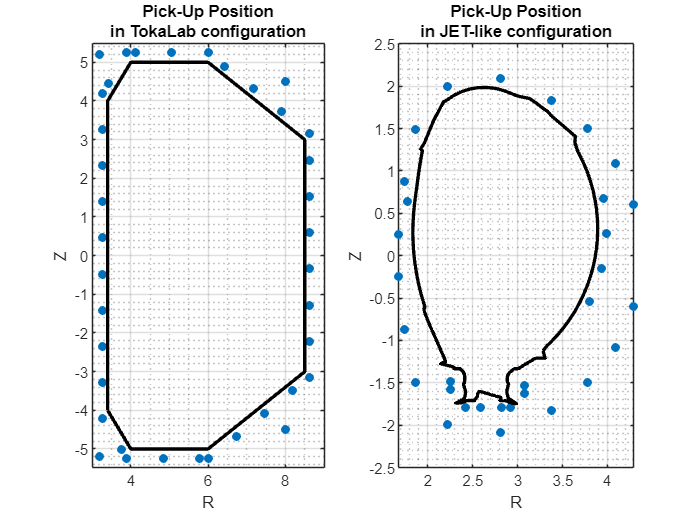

equi_JET = equi_JET.equi_pp2();
equi_JET  = equi_JET.compute_profiles();

PickUp_JET = Diag_PickUpCoils(); % To initialise the diagnostic
PickUp_JET = PickUp_JET.Upload(1,machine_JET); % To upload the configuration and the geometrical data 
PickUp_JET = PickUp_JET.measure(equi_JET); % To simulate the measurements

figure(1)
clf
subplot(1,2,1)
PickUp.plot_geo()
title("Pick-Up Position" + newline + "in TokaLab configuration")
hold on
plot(geo.wall.R, geo.wall.Z, '-k', 'LineWidth',2)
axis equal
xlim([3 9])

subplot(1,2,2)
PickUp_JET.plot_geo()
title("Pick-Up Position" + newline + "in JET-like configuration")
hold on
plot(geo_JET.wall.R, geo_JET.wall.Z, '-k', 'LineWidth',2)

#### 2.1.2 Example 2: Noisy measurements 

figure(2)
clf

subplot(1,2,1)
PickUp.plot_meas();
title("Pick-Up Measurements")


Let us now consider to add noise to measurements, in the third panel on the left we will se the effect of the noise on measurements. To add noise, it is necessary to define it as follows and then to run again the PickUp.measure function. 

PickUp.config.noise_random_absolute_intensity = 50e-3; % [T], a typical value for pick-up noise value.
PickUp.config.noise_random_proportional_intensity = 0.1; % [1] 
PickUp = PickUp.measure(equi)

PickUp =   Diag_PickUpCoils with properties:

          R: [3.2700 3.7514 3.9000 4.8357 5.7715 6 6.7307 7.4614 8.1921 8.6250 8.6250 8.6250 8.6250 8.6250 8.6250 8.6250 8.6250 7.8943 7.1636 6.4329 6 5.0643 4.1285 3.9000 3.4186 3.2700 3.2700 3.2700 3.2700 3.2700 3.2700 3.2700 3.2700 3.2700 4.2000 … ]
          Z: [-4.2000 -5.0024 -5.2500 -5.2500 -5.2500 -5.2500 -4.6654 -4.0809 -3.4963 -3.1500 -2.2143 -1.2785 -0.3428 0.5930 1.5287 2.4645 3.1500 3.7346 4.3191 4.9037 5.2500 5.2500 5.2500 5.2500 4.4476 4.2000 3.2643 2.3285 1.3928 0.4570 -0.4787 … ]
          n: [3×42 double]
          B: [0.2778 0.1973 -0.7091 -0.4694 -0.2553 0.1384 0.2602 0.4155 0.5703 0.9067 0.8375 0.8124 0.9730 0.9236 1.0823 0.8058 0.1877 0.4079 0.3868 0.6233 0.4289 0.0641 -0.4612 -0.4090 -0.0570 0.0339 0.0979 0.8632 1.5952 1.4711 1.0676 1.1074 0.8605 … ]
    sigma_B: [0.0594 0.0534 0.0876 0.0728 0.0556 0.0528 0.0614 0.0704 0.0801 0.1028 0.1049 0.1051

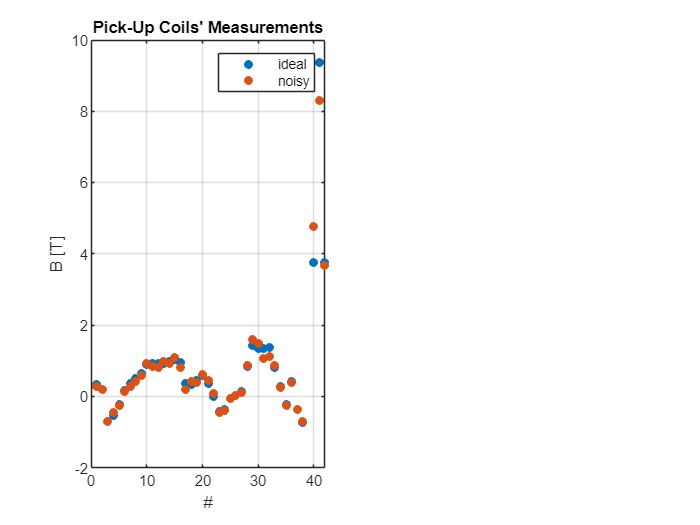

subplot(1,2,1)
hold on
PickUp.plot_meas();
title("Pick-Up Coils' Measurements")
legend(["ideal", "noisy"])

Note that, in this case, the value for $\sigma_B$ has varied respect to the one shown previously:

 disp(PickUp.sigma_B)

    0.0594    0.0534    0.0876    0.0728    0.0556    0.0528    0.0614    0.0704    0.0801    0.1028    0.1049    0.1051    0.1053    0.1092    0.1144    0.1065    0.0611    0.0593    0.0659    0.0766    0.0616    0.0500    0.0660    0.0626    0.0504    0.0500    0.0517    0.0980    0.1517    0.1421    0.1420    0.1462    0.0950    0.0572    0.0557    0.0649    0.0629    0.0883    0.9390    0.3783    0.9390    0.3783



### 2.2 Flux Loops

Flux Loops are magnetic induction sensors measuring themagnetic flux linked to the coils ([Donné at al, 2007](https://doi.org/10.1088/0029-5515/47/6/S07), [Hutchinson, 2002](https://doi.org/10.1017/CBO978051161363), [Wesson, 2014](https://scipub.euro-fusion.org/wp-content/uploads/2014/11/JETR99013.pdf)). Beeing i the i-th measurement, each measurement is modelled as reproted below (bein R_i and Z_i the coordinate of each coil's centre projected on the poloidal section): 


$$\psi_{{\mathrm{FL}}_i } =\psi \left(R_i ,Z_i \right)$$
 

In this case, the relevant quantities used in the Diag_FluxLoops class to simulate the flux loops are the following: 

- R, the horizontal coordinate

- Z, the vertical coordinate

- $\psi$, the measured magnetic field

- $\sigma_{\psi }$, the associated uncertainty to measure the magnetic field

- unit, the unit of measurement, in this case [Wb/rad]

- config, the structure containing the information related to the configuration

- ideal, the structure containing the measurements without noise

The principle of working is very similar to the Pick-Up Coils and to the Saddle Coils (introduced in 2.3). This similarity can be found also in the structure of the function. The Upload function and Measure function work exactly the same as introduced for Pick-Up Coils, with the only difference in the field to interpolate: in this case this is the specific magnetic flux [Wb/rad].

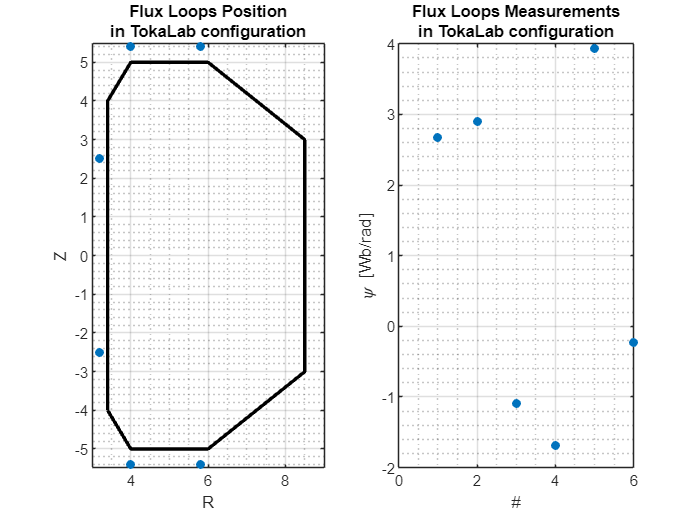

FluxLoops = Diag_FluxLoops(); % To initialise the diagnostic
FluxLoops = FluxLoops.Upload(1,machine); % To upload the configuration and the geometrical data 
FluxLoops = FluxLoops.measure(equi); % To simulate the measurements

figure(3)
clf
subplot(1,2,1)
FluxLoops.plot_geo()
title("Flux Loops Position" + newline + "in TokaLab configuration")
hold on
plot(geo.wall.R, geo.wall.Z, '-k', 'LineWidth',2)
axis equal
xlim([3 9])

subplot(1,2,2)
FluxLoops.plot_meas()
title("Flux Loops Measurements" + newline + "in TokaLab configuration")

### 2.3 Saddle Loops

Saddle Loops (or Saddle Coils) are the last type of induction sensors implemented in TokaLab. They measure the differential magnetic flux linked to two extremities of a saddle-shaped coil. Also in this case, references can be found in [Donné at al, 2007](https://doi.org/10.1088/0029-5515/47/6/S07), [Hutchinson, 2002](https://doi.org/10.1017/CBO978051161363) and [Wesson, 2014](https://scipub.euro-fusion.org/wp-content/uploads/2014/11/JETR99013.pdf).

The difference between the two saddle's extremities (1 and 2) are calculated clockwise. The simulated measurement can be formulated as: 


$$\Delta \psi_{{\mathrm{SL}}_i } =\psi \left(R_2 ,Z_2 \right)-\psi \left(R_1 ,Z_1 \right)$$


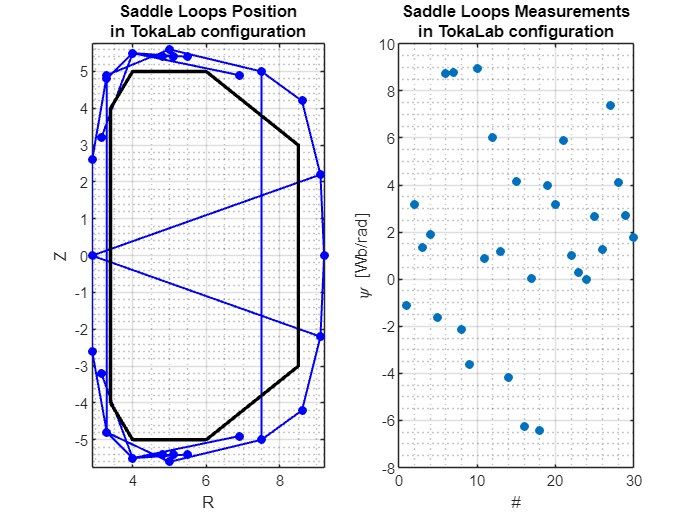

SaddleLoops = Diag_SaddleCoils(); % To initialise the diagnostic
SaddleLoops = SaddleLoops.Upload(1,machine); % To upload the configuration and the geometrical data 
SaddleLoops = SaddleLoops.measure(equi); % To simulate the measurements

figure(4)
clf
subplot(1,2,1)
SaddleLoops.plot_geo()
title("Saddle Loops Position" + newline + "in TokaLab configuration")
hold on
plot(geo.wall.R, geo.wall.Z, '-k', 'LineWidth',2)
axis equal
% xlim([3 9])

subplot(1,2,2)
SaddleLoops.plot_meas()
title("Saddle Loops Measurements" + newline + "in TokaLab configuration")

The left panel of Figure 4 reports the projection of the extremities' links: saddle coils do not cross the poloidal section. As for the flux loops and pick-up coils they are local external diagnostics. 

### 2.4 Thomson Scattering

Thomson scattering is a cornerstone diagnostic for tokamak plasmas, offering direct and non-perturbative measurements of electron temperature and density ([Hutchinson, 2002,](https://doi.org/10.1017/CBO978051161363) [Wesson, 2014](https://scipub.euro-fusion.org/wp-content/uploads/2014/11/JETR99013.pdf)). By directing a high-power laser through the plasma, the system captures the light scattered by electrons, whose spectral characteristics reveal the plasma's thermal and density properties: the scattered light shifts its wavelength due to the Doppler effect, resulting in a variation of the width of the spectrum. The variation of the spectrum's width allows to quantify the plasma temperature, while the intensity of the collected light's spectrum relates to the electron density. This method stands out for its ability to provide spatially and temporally resolved data. Its reliability and precision have cemented its role in both experimental and next-generation tokamaks, where accurate diagnostics are critical for advancing plasma physics and fusion energy development.

 At the moment, in TokaLab the synthetic diagnostics interpolates the electron density and electron temperature fields in the points in which the Thomson Scattering is simulated. Further work on this synthetic diagnostic could involve the simulation of the ray optics.


$$\begin{array}{l}
{N_e }_{{\mathrm{TS}}_i } =N_e \left(R_i ,Z_i \right)\\
{T_e }_{{\mathrm{TS}}_i } =T_e \left(R_i ,Z_i \right)
\end{array}$$


As based on the interpolation of fields coming from the equilibrium, the functions for the simulation of measurements work in the same way already introduced in previous sections. For the Thomson Scattering we discuss the example of using two different configurations for the diagnostics in the DTT-like geometry.

#### 2.4.1 Example 1: Mounting two Thomson Scattering in the same tokamak

%% To introduce a new geometry it is necessary to run again the equilibrium
tok_DTT = tokamak();

% upload the geometry information of your tokamak
machine_DTT = "DTT-like";
tok_DTT = tok_DTT.machine_upload(machine_DTT);

DTT-like


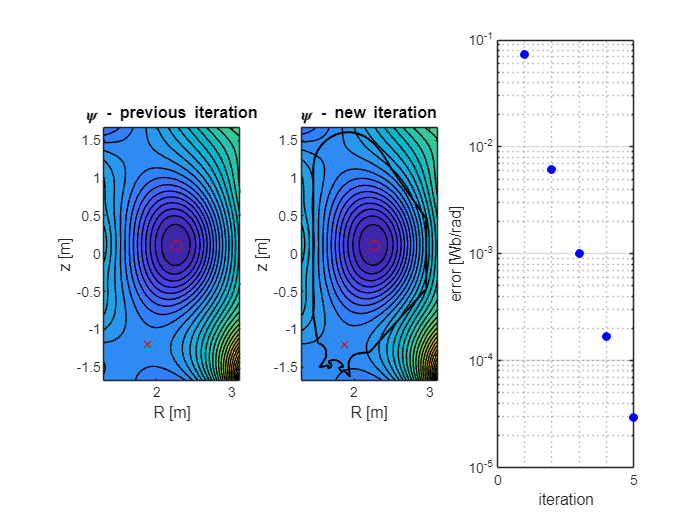

tok_DTT = tok_DTT.scenario_upload(1);
tok_DTT = tok_DTT.kinetic_upload();

% initialise the class geometry
geo_DTT = geometry;
geo_DTT = geo_DTT.import_geometry(tok_DTT);
geo_DTT = geo_DTT.build_geometry();
geo_DTT = geo_DTT.inside_wall();

% initialise the equlibrium class
equi_DTT = equilibrium;
equi_DTT = equi_DTT.import_configuration(geo_DTT,tok_DTT.config);
equi_DTT = equi_DTT.import_classes();
equi_DTT.separatrix = equi_DTT.separatrix.build_separatrix(equi_DTT.config.separatrix,equi_DTT.geo);

new_points_R = [];
new_points_Z = [];

equi_DTT = equi_DTT.solve_equilibrium_dimless();

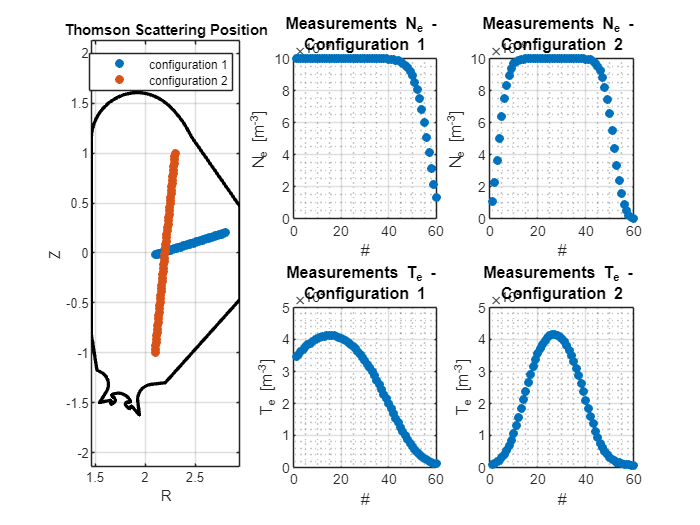

equi_DTT = equi_DTT.equi_pp2();
equi_DTT  = equi_DTT.compute_profiles();

configuration_1 = 1;
TS_DTT_1 = Diag_ThomsonScattering();
TS_DTT_1 = TS_DTT_1.Upload(configuration_1, machine_DTT);
TS_DTT_1 = TS_DTT_1.measure(equi_DTT);

configuration_2 = 2;
TS_DTT_2 = Diag_ThomsonScattering();
TS_DTT_2 = TS_DTT_2.Upload(configuration_2, machine_DTT);
TS_DTT_2 = TS_DTT_2.measure(equi_DTT);

figure(5)
clf
subplot(2,3,[1 4])
TS_DTT_1.plot_geo()
title("Thomson Scattering Position")
hold on
TS_DTT_2.plot_geo()
plot(geo_DTT.wall.R, geo_DTT.wall.Z, '-k', 'LineWidth',2)
axis equal
legend(["configuration 1", "configuration 2"])

subplot(2,3,2)
TS_DTT_1.plot_ne_meas()
title("Ideal measurements N_e - " + newline + "Configuration 1")

subplot(2,3,3)
TS_DTT_2.plot_ne_meas()
title("Ideal measurements N_e - " + newline + "Configuration 2")
subplot(2,3,5)
TS_DTT_1.plot_Te_meas()
title("Ideal measurements T_e - " + newline + "Configuration 1")

subplot(2,3,6)
TS_DTT_2.plot_Te_meas()
title("Ideal measurements T_e - " + newline + "Configuration 2")